# Analyzing color histogram using eigenfaces algorithm 

Normalize matrix A by making a matrix by repeating a column vector that contains the sum of each row, and subtracting the resulting matrix from A. 

A1 = training_data

A1 =         2242        8463         273        8986        8592        2425        1610        1916         666         117        9320         595        1973       33246        9857       12435        9215       35565       18756        4849        5230         474         550        1819         299          78        4878          37           0         364          77         113         137         105           0        1326          73         329          31          12
         828        1348          86         780        1710         960         568         376         233          70        1749         272        1229         884        1516        1840        2386        1091        4010        1317         836         178         127        2113          54          45        1355          10           0          42          42          32          26          38           0         230          11          50           9           4
         875         358         

A = A1 - repmat((sum(A1,2)./40),1,40);
clear A1

Find decomposition (basically Eigenvectors and eigenvalues) of covariance matrix

U is a matrix of the eigenvalues (106x106)

S is variance in direction of egienvector s^2 are eigenvalues (106x106)

[U,S,V] = svd(transpose(A)*A);

Find U with equation ui = A*vi

 U1 (65536x106) 

U1 = (A*V);
clear U
clear S
clear V

Determine which eigenvectors from U are most important (which have the largest eigenvalues, but the first few have to do with lighting, so dispose of those), and throw out all the unnecessary eigenvectors and values. 

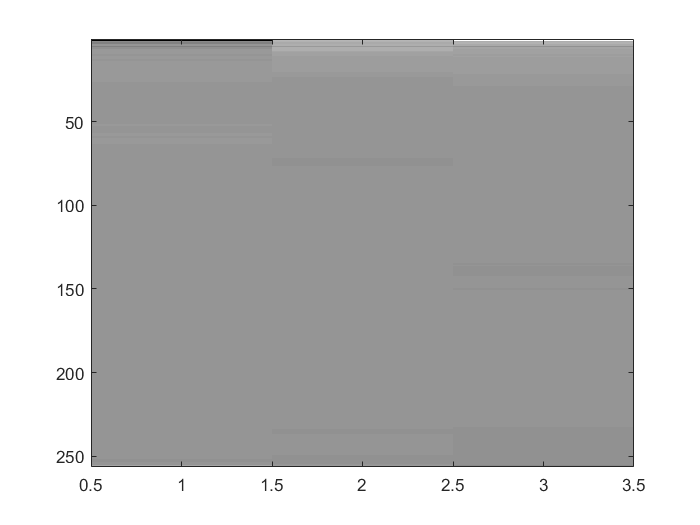

U20 = U1(:,4:18); % extract 20 entries
imagesc(reshape(U20(:,1), 256, 3)); colormap('gray') %display an eigenface

Then find out how much of each eigenvector is used to represent each face (find weights).

Weights = Transpose(U)*Image

Wtrain = transpose(U20)*A;

## When given a new face, find the weights and compare those to all existing weights 

Reshape and normalize in the same way as with the training data

Atest = test_data

Atest =         6123        5041       13493         580        3753        9812         821        7020       10990         150        2111        9344         445        2365          20       13358       35282           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
        1022        1159        1671         120        1145        1579         138        1232        6052         284         471        1719         160         880          44        1882        1709           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
        1334         219        1407         138        1305        1306         172        1209        1722         143         545         531         158         893          21        1414         724           0      


Wtest = transpose(U20)*Atest;

## Run for all faces in test set and determine accuracy

Change number of eigenvectors and run again

U20 = U1(:,4:18); %change which and how many eigenvectors are used
Wtrain = transpose(U20)*A;
Wtest = transpose(U20)*Atest;

num_true = 0;
num_false = 0;
tagged_false = 0;
tagged_false_list = [];
false_list = [];
for n = 1:32
    Wn = Wtest(:,n);
    WL = zeros(1,40);
    for i = 1:40
       WL(i) = WL(i) + sum(abs(Wtrain(:,i)-Wn));
    end
    [M,I] = min(WL);
    if sum(abs(Wtrain(:,i)-Wn)) > 350000000
%       disp("Probably incorrect")
       tagged_false = tagged_false + 1;
       tagged_false_list = [tagged_false_list,n];
    end
    if train_tags(I) == test_tags(n)
        num_true = num_true+1;
        %disp(sum(WL))
    else
        num_false = num_false+1;
        in = [I,n];
        false_list = [false_list, n];
    end
end

disp("Number correct: "+ num_true)

Number correct: 26


disp("Number incorrect: "+ num_false)

Number incorrect: 6


disp("Percentage correct: "+num_true/(num_false+num_true)*100)

Percentage correct: 81.25


disp("Tagged False: "+tagged_false)

Tagged False: 3


false_list = sort(false_list)

false_list =      4     5     6    10    12    17


for j = (size_false_list(:,2))

    imagesc(grayfaces_train(:,:,false_list(j-1))); colormap('gray')

    y_train.name(j)

    imagesc(grayfaces_test(:,:,n)); colormap('gray')

    y_test.name(n)

end